# EXERCISE #3 : Audio Simulation in a Bluetooth LE Piconet

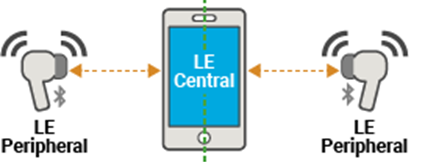

**In this exercise, you will:**

- Establish an Asynchronous Connection-Oriented (ACL) link and a Connected Isochronous Stream (CIS) connection.

- Model audio streaming at different bit rates.

- Simulate the scenario and visualize packet communication along with the state transitions of source and sink nodes over time.

- Enable a WLAN interferer network and visualize the resulting interference.

all_figs = findall(0, 'type', 'figure');close(all_figs); % close all previous windows
p = addpath(fullfile('.', 'Shared', 'Helpers'), fullfile('.', 'Shared', 'Utilities')); % Add path to helpers and utilities
wirelessnetworkSupportPackageCheck
rng(1,"twister");
networkSimulator = wirelessNetworkSimulator.init;
simulationTime = 0.5;

#### Create a Bluetooth LE node, specifying the role as `"central"`.

source = bluetoothLENode("central", ...
    "Name","Central", ...
    Position=[0 0 0], ...
    TransmitterPower=-20, ...
    TransmitterGain=0, ...
    ReceiverGain=0, ...
    ReceiverSensitivity=-100);  

#### Create Bluetooth LE nodes, specifying the role as `"peripheral"` and name as leftsink 

leftSink = bluetoothLENode("Peripheral", ...
    Position=[7 0 0], ...
    Name="leftsink", ...
    TransmitterPower=-20, ...
    TransmitterGain=0, ...
    ReceiverGain=0, ...
    ReceiverSensitivity=-100);

#### Create Bluetooth LE nodes, specifying the role as `"peripher`al" and name as rightsink 

rightSink = bluetoothLENode("Peripheral", ...
    Position=[7.2 0 0], ...
    Name="rightsink", ...
    TransmitterPower=-20, ...
    TransmitterGain=0, ...
    ReceiverGain=0, ...
    ReceiverSensitivity=-100);

To set the timing of ACL and CIS events, specify these values.

- Connection interval 

- Isochronous (ISO) interval 

connectionInterval = 0.10;  % In seconds
phymode = "LE1M";
% Bluetooth LE Audio specific parameters  
isoInterval = 0.050;        % In seconds
numSubevents = 2;
burstNumber = 1; 
subInterval = 5e-3;         % In seconds

# Task #1/3 Create a Bluetooth LE CIS configuration 

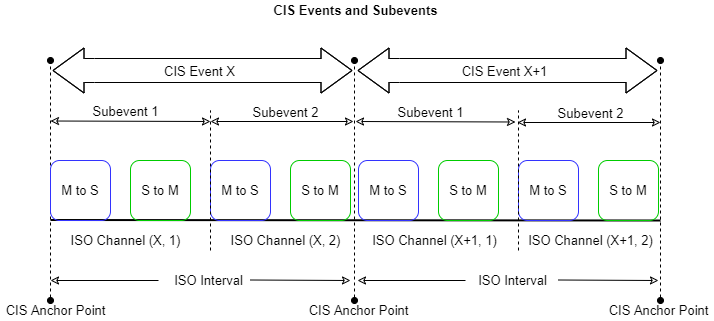

- **ISO Interval:** Time between the start of two consecutive isochronous events.

- **Number of Subevents:** Count of time slots available inside each ISO Interval.

- **Burst Number (BN):** Number of unique payloads in a CIS event

- **Sub-Interval:** Time between the start of two consecutive subevents in CIS

% Use bluetoothLECISConfig() function to set Bluetooth LE connection configuration parametrs
% Write configuration in a variable named "cfgCIS"
% Hint: Type "doc bluetoothLECISConfig" in the MATLAB Command Window, and see the "Syntax" section.
% Note : use the following values to start with
% ISOInterval=isoInterval
% NumSubevents=numSubevents
% BurstNumber=burstNumber
% SubInterval= subInterval
% MaxPDU= 251 
% FlushTimeout= 1
% TMSS= 150e-6
% TIFS= 150e-6 

% Write your code here
% cfgCIS = 

len = subeventLength(cfgCIS,phymode)

#### Create a Bluetooth LE connection configuration 

cfgConnection = bluetoothLEConnectionConfig(ConnectionInterval=connectionInterval, ...
    ActivePeriod=0.001, ...
    MaxPDU=27, ...
    PHYMode=phymode);

# Task #2/3 Configure the ACL and CIS connection between the source and the left sink

cfgConnection.AccessAddress = "5DA44270";
cfgConnection.ConnectionOffset = 0; 
% Use configureConnection() function to configure the ACL nas CIS connection 
% Hint: Type "doc configureConnection" in the MATLAB Command Window, and see the "Syntax" section. 
% Set the LHS as [leftConnCfg,leftCISCfg] =
% Note : use the following values to start with
% cfgConnection, ...
% source, ...
% leftSink, ...
% CISConfig=cfgCIS  

% Write your code here                                                                                   
% [leftConnCfg,leftCISCfg] = 

#### Configure the ACL and CIS connection between the source and the right sink

cfgConnection.AccessAddress = "5DA44271";
cfgConnection.ConnectionOffset = 0.05; % In seconds
[rightConnCfg,rightCISCfg] = configureConnection(cfgConnection, ...
    source, ...
    rightSink, ...
    CISConfig=cfgCIS);

#### Add the source and sink nodes to the wireless network simulator.

nodes = [source leftSink rightSink];
addNodes(networkSimulator,nodes);

#### Add Audio Traffic

dataRate = 64; % In kbps
leftSinkTraffic = networkTrafficOnOff(DataRate=dataRate,PacketSize=cfgCIS.MaxPDU,GeneratePacket=true,OnTime=Inf,OffTime=0);
rightSinkTraffic = networkTrafficOnOff(DataRate=dataRate,PacketSize=cfgCIS.MaxPDU,GeneratePacket=true,OnTime=Inf,OffTime=0);
plotTrafficPattern(simulationTime,rightSinkTraffic)

# Task #3/3 Add audio traffic between source and left sink  

% Add traffic from source to destination
% Use addTrafficSource() function to add the traffic
% Set the first argument to the central node object: source 
% Set the other arguments in the following sequence
% leftSinkTraffic
% DestinationNode=leftSink
% CISConfig=leftCISCfg
% Hint: Click the link below and see the "Syntax" section.

### [Help on adding traffic source to a node ](https://in.mathworks.com/help/bluetooth/ref/bluetoothlenode.addtrafficsource.html)

% Write your code here

#### Add audio traffic between source and right sink  

addTrafficSource(source,rightSinkTraffic,DestinationNode=rightSink,CISConfig=rightCISCfg);

#### Add Custom Path Loss Model

cfgPathloss = bluetoothPathLossConfig(Environment="Home");
pathlossHandle = @(rxInfo,txData) updatePathLoss(rxInfo,txData,cfgPathloss); % Path loss function
addChannelModel(networkSimulator,pathlossHandle);

#### To enable the WLAN BSS

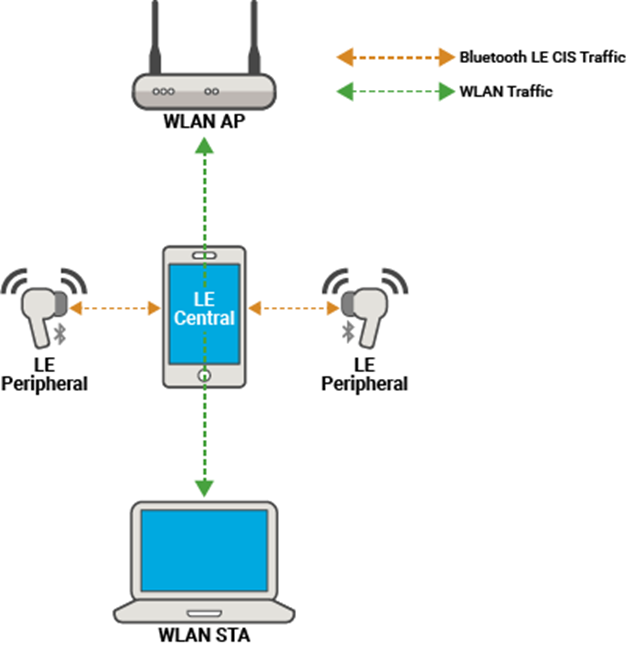

enableWLANNetwork = false;
if enableWLANNetwork
    % Set WLAN band and channel
    bandAndChannel = [2.4 7];
    % Configure Access Point (AP)
    apDeviceConfig = wlanDeviceConfig(Mode="AP",BandAndChannel=bandAndChannel,TransmitPower=20,InterferenceModeling="overlapping-adjacent-channel");
    % Configure Station (STA)
    staDeviceConfig = wlanDeviceConfig(Mode="STA",BandAndChannel=bandAndChannel,TransmitPower=20,InterferenceModeling="overlapping-adjacent-channel");
    % Create an AP with the specified configuration
    wlanAPNode = wlanNode(DeviceConfig=apDeviceConfig,Name="WLAN AP",Position=[3.5 0 0],MACFrameAbstraction=false,PHYAbstractionMethod="none");
    % Create an STA with the specified configuration
    wlanSTANode = wlanNode(DeviceConfig=staDeviceConfig,Name="WLAN STA",Position=[5.5 0 0], MACFrameAbstraction=false,PHYAbstractionMethod="none");
    % Set up the WLAN network
    associateStations(wlanAPNode,wlanSTANode,BandAndChannel=bandAndChannel);
    % Add AP-to-STA traffic
    ap2staTraffic = networkTrafficOnOff(OnTime=Inf,OffTime=0,DataRate=35000,PacketSize=200);
    addTrafficSource(wlanAPNode,ap2staTraffic,DestinationNode=wlanSTANode);
    % Add STA-to-AP traffic
    sta2apTraffic = networkTrafficOnOff(OnTime=Inf,OffTime=0,DataRate=35000,PacketSize=200);
    addTrafficSource(wlanSTANode,sta2apTraffic,DestinationNode=wlanAPNode);
    % Add WLAN nodes to the network simulator
    wlanNodes = [wlanAPNode wlanSTANode];
    addNodes(networkSimulator,wlanNodes)
end

#### Visualize Packet Transitions

helperPlotPacketTransitions(networkSimulator.Nodes,simulationTime,FrequencyPlotFlag=true);

#### **Simulation and Results**

clear packetCaptureObj; % Clear the packet capture handle if exists
packetCaptureObj = helperPacketCapture(nodes,"pcap");
run(networkSimulator,simulationTime);

Retrieve the statistics of all the nodes. For more information about Bluetooth LE node statistics, see [Bluetooth LE Statistics](docid:bluetooth_ug#mw_675e1436-48b0-41db-bba4-5f34fb750a31).

sourceStats = nodes(1).statistics;
leftSinkStats = nodes(2).statistics;
rightSinkStats = nodes(3).statistics;
leftSinkRxThroughtput = (leftSinkStats.LL.CISStatistics.ReceivedBytes*8)/(simulationTime*1000);
rightSinkRxThroughtput = (leftSinkStats.LL.CISStatistics.ReceivedBytes*8)/(simulationTime*1000);
fprintf(['Left Sink Rx Throughput: %f kbps\n ' ...
    'Right Sink Rx Throughput: %f kbps\n ' ...
    ], ...
    leftSinkRxThroughtput , ...
    rightSinkRxThroughtput);

#### App Layer KPIs

leftSinkLatency = kpi(source,leftSink,"latency",Layer="App");
rightSinkLatency = kpi(source,rightSink,"latency",Layer="App");

#### Link Layer KPIs

leftSinkThroughput = kpi(source,leftSink,"throughput",Layer="LL");
leftSinkPLR = kpi(source,leftSink,"PLR",Layer="LL");
rightSinkThroughput = kpi(source,rightSink,"throughput",Layer="LL");
rightSinkPLR = kpi(source,rightSink,"PLR",Layer="LL");

fprintf(['Left Sink Latency: %f seconds\n' ...
    'Left Sink Tx Throughput: %f kbps\n ' ...
    'Left Sink Packet Loss Ratio: %f \n ' ...
    'Right Sink Latency: %f seconds\n ' ...
    'Right Sink Tx Throughput: %f kbps\n ' ...
    'Right Sink PLR: %f \n '], ...
    leftSinkLatency, ...
    leftSinkThroughput, ...
    leftSinkPLR, ...
    rightSinkLatency, ...
    rightSinkThroughput, ...
    rightSinkPLR);
delete(packetCaptureObj);

### Custom Path Loss Model

Create a custom path loss model function by using the [`bluetoothPathLoss`](docid:bluetooth_ref#mw_f25d6cf1-a629-41c3-be12-300444721771) function and attach it to the wireless network simulator.

function rxData = updatePathLoss(rxInfo,txData,pathlossCfg)
    % Apply pathloss and update output signal
    rxData = txData;
    % Calculate distance between transmitter and receiver in meters
    distance = norm(rxData.TransmitterPosition - rxInfo.Position);
    pathloss = bluetoothPathLoss(distance,pathlossCfg);
    rxData.Power = rxData.Power - pathloss; % In dBm
    scale = 10.^(-pathloss/20);
    [numSamples, ~] = size(rxData.Data);
    rxData.Data(1:numSamples,:) = rxData.Data(1:numSamples,:)*scale;
end

*Copyright 2023-2024 The MathWorks, Inc.*